# **Stress Concentration in Plate with Circular Hole**

This live script is written as a guided walkthrough for a verification benchmark. It compares a known structural response with the result produced by the OpenSeesMatlab workflow. Read the text cells first, then run each code cell in order so that the variables, model state, and recorded results are available for the later sections.

Perform a 2-D plane-stress elasticity analysis.

A thin rectangular plate under a uniaxial tension has a uniform stress distribution. Introducing a circular hole in the plate disturbs the uniform stress distribution near the hole, resulting in a significantly higher than average stress. Such a thin plate, subject to in-plane loading, can be analyzed as a 2-D plane-stress elasticity problem. In theory, if the plate is infinite, then the stress near the hole is three times higher than the average stress. For a rectangular plate of finite width, the stress concentration factor is a function of the ratio of hole diameter to the plate width. This example approximates the stress concentration factor using a plate of a finite width.

See matlab PDE toolbox examples: [Stress Concentration in Plate with Circular Hole - MATLAB & Simulink](https://www.mathworks.com/help/pde/ug/stress-concentration-in-plate-with-circular-hole.html)

### Partial Differential Equation Toolbox Solving

The following commands carry out this step of the workflow. Run this cell after the previous sections so the required variables and model state already exist.

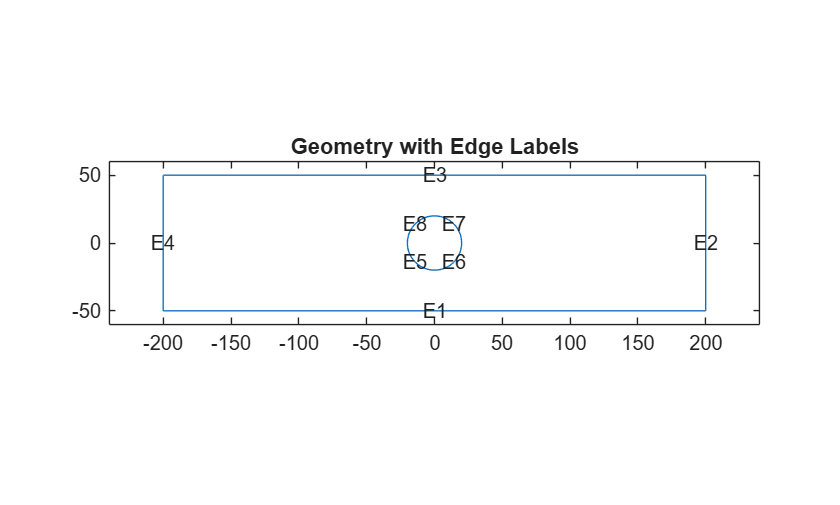

clc; clear; close all;

radius = 20.0;
totalWidth = 50.0;
totalLength = 4*totalWidth;

R1 = [3 4 -totalLength  totalLength ...
           totalLength -totalLength ...
          -totalWidth -totalWidth totalWidth totalWidth]'; 
C1 = [1 0 0 radius 0 0 0 0 0 0]';

gdm = [R1 C1];
ns = char('R1','C1');
g = decsg(gdm,'R1 - C1',ns');

figure
pdegplot(g,EdgeLabel="on");
axis([-1.2*totalLength 1.2*totalLength -1.2*totalWidth 1.2*totalWidth])
title("Geometry with Edge Labels")

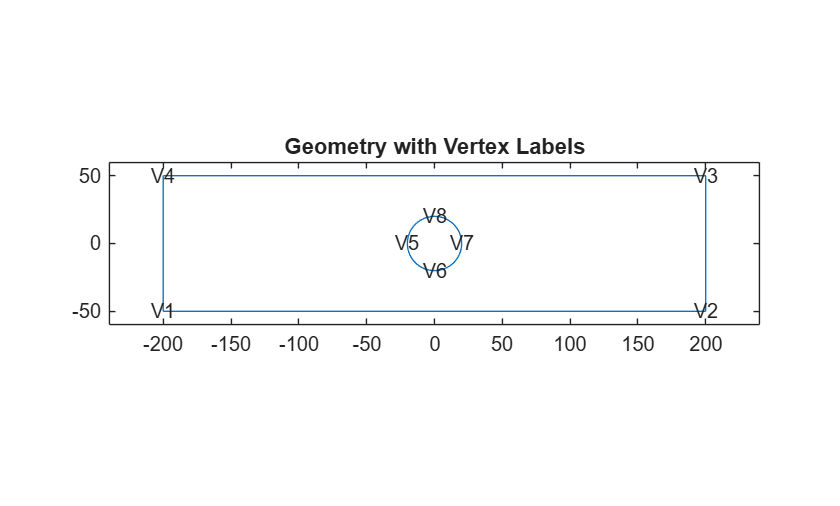

figure
pdegplot(g,VertexLabels="on");
axis([-1.2*totalLength 1.2*totalLength -1.2*totalWidth 1.2*totalWidth])
title("Geometry with Vertex Labels")

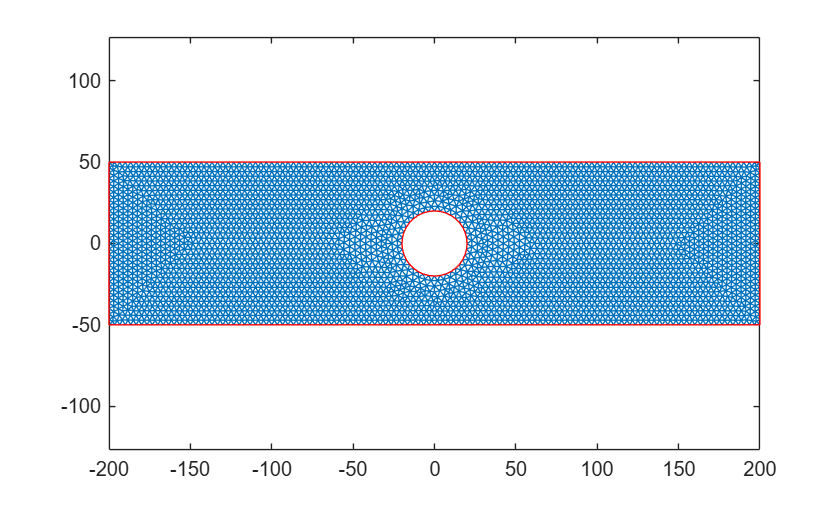

model = femodel(AnalysisType="structuralStatic", ...
                Geometry=g);

E  = 200e3;
nu = 0.25;

model.MaterialProperties = materialProperties( ...
    YoungsModulus = E, ...
    PoissonsRatio = nu);

model.EdgeLoad(2) = edgeLoad(SurfaceTraction=[100;0]);
model.EdgeBC(4) = edgeBC(XDisplacement=0);
model.VertexBC(1) = vertexBC(YDisplacement=0);

model = generateMesh(model,Hmax=radius/6, GeometricOrder="linear");
figure
pdemesh(model)

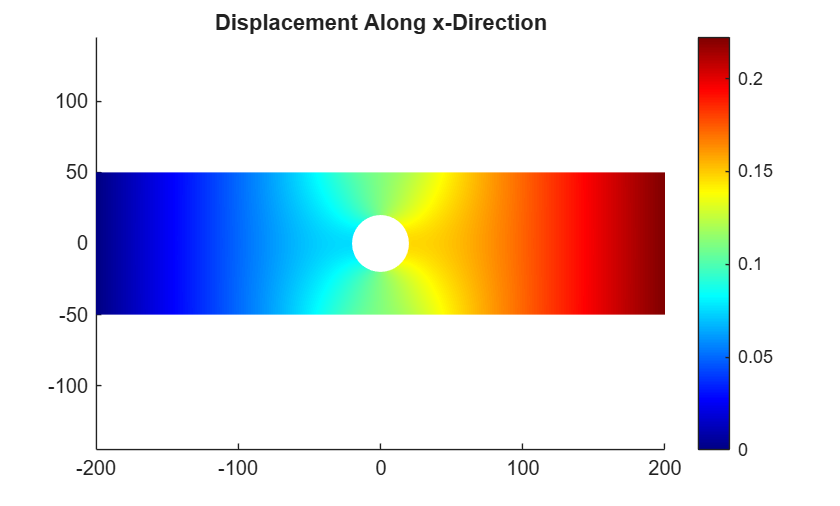

R = solve(model);
maxUxPDE = max(R.Displacement.ux);
maxVonMisesStressPDE = max(R.VonMisesStress);
maxSxxPDE = max(R.Stress.sxx);

figure
pdeplot(R.Mesh,XYData=R.Displacement.ux, ...
        ColorMap="jet")
axis equal
title("Displacement Along x-Direction")

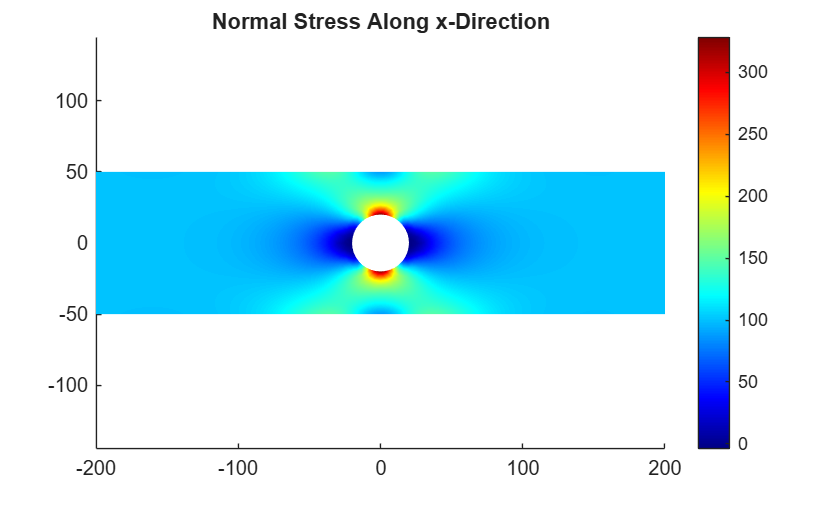

figure
pdeplot(R.Mesh,XYData=R.Stress.sxx, ...
        ColorMap="jet")
axis equal
title("Normal Stress Along x-Direction")

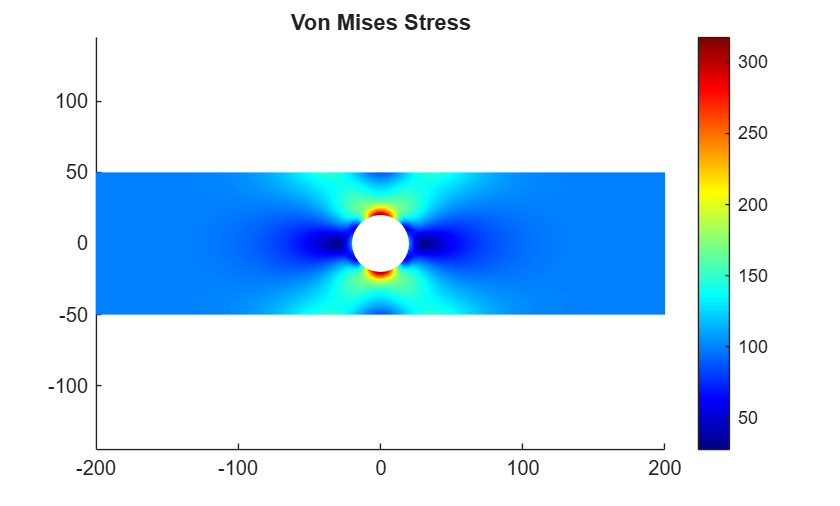

figure
pdeplot(R.Mesh,XYData=R.VonMisesStress, ...
        ColorMap="jet")
axis equal
title("Von Mises Stress")

### OpenSeesMatlab Solving

#### Extract PDE mesh data

mesh = model.Mesh;

% PDE mesh
%   Nodes    : 2 x nNode
%   Elements : 3 x nElem
nodes = mesh.Nodes.';       % nNode x 2
elems = mesh.Elements.';    % nElem x 3

nNode = size(nodes,1);
nElem = size(elems,1);

if size(elems,2) ~= 3
    error('This conversion script expects a linear triangular mesh.');
end

%% ------------------------------------------------------------------------
% 3) Identify boundary entities from PDE labels
%% ------------------------------------------------------------------------
loadEdgeID   = 2;
fixEdgeID    = 4;
fixVertexID  = 1;

loadNodeIDs  = unique(findNodes(mesh, "region", "Edge",   loadEdgeID));
fixEdgeNodes = unique(findNodes(mesh, "region", "Edge",   fixEdgeID));
fixVertNodes = unique(findNodes(mesh, "region", "Vertex", fixVertexID));

loadNodeIDs  = loadNodeIDs(:);
fixEdgeNodes = fixEdgeNodes(:);
fixVertNodes = fixVertNodes(:);

%% ------------------------------------------------------------------------
% 4) Build boundary segments on the loaded edge
%% ------------------------------------------------------------------------
TR = triangulation(elems, nodes);
bedges = freeBoundary(TR);              % nb x 2 boundary node pairs

isLoadSeg = all(ismember(bedges, loadNodeIDs.'), 2);
loadSegs  = bedges(isLoadSeg, :);

if isempty(loadSegs)
    warning('No boundary segments found on PDE edge %d.', loadEdgeID);
end

%% ------------------------------------------------------------------------
% 5) Convert edge traction to equivalent nodal loads
%
% For a 2-node linear boundary segment:
%   f_e = \int N^T t * thk ds
% For constant traction:
%   f_e = (L*thk/2) * [tx; ty; tx; ty]
%% ------------------------------------------------------------------------
thickness = 1;           % choose consistent thickness for Tri31
traction  = [100; 0];      % same as PDE edge load

nodalLoads = zeros(nNode, 2);

for i = 1:size(loadSegs,1)
    s = loadSegs(i,:);
    x1 = nodes(s(1), :);
    x2 = nodes(s(2), :);
    L  = norm(x2 - x1);

    fe = (L * thickness / 2) * [traction(:); traction(:)];   % 4x1

    nodalLoads(s(1), :) = nodalLoads(s(1), :) + fe(1:2).';
    nodalLoads(s(2), :) = nodalLoads(s(2), :) + fe(3:4).';
end

#### Build OpenSees model

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 2);

% Nodes
for i = 1:nNode
    ops.node(i, nodes(i,1), nodes(i,2));
end

% Material + elements
matTag = 1;
type2D = 'PlaneStress';

ops.nDMaterial('ElasticIsotropic', matTag, E, nu);

for e = 1:nElem
    n = elems(e,:);
    ops.element('Tri31', e, n(1), n(2), n(3), thickness, type2D, matTag);
end

[OpenSees] Tri31 - Written by Roozbeh G. Mikola and N.Sitar, UC Berkeley



%% ------------------------------------------------------------------------
% 7) Boundary conditions
%
% EdgeBC(4): XDisplacement = 0  -> fix ux on all nodes of edge 4
% VertexBC(1): YDisplacement = 0 -> fix uy on node(s) of vertex 1
%% ------------------------------------------------------------------------
fixX = false(nNode,1);
fixY = false(nNode,1);

fixX(fixEdgeNodes) = true;
fixY(fixVertNodes) = true;

for i = 1:nNode
    if fixX(i) || fixY(i)
        ops.fix(i, double(fixX(i)), double(fixY(i)));
    end
end

%% ------------------------------------------------------------------------
% 8) Loads
%% ------------------------------------------------------------------------
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

tol = 0;
for i = 1:nNode
    fx = nodalLoads(i,1);
    fy = nodalLoads(i,2);

    if abs(fx) > tol || abs(fy) > tol
        ops.load(i, fx, fy);
    end
end

%% ------------------------------------------------------------------------
% 9) Static analysis
%% ------------------------------------------------------------------------
ops.constraints('Plain');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', 1e-8, 50);
ops.algorithm('Newton');
ops.integrator('LoadControl', 1/2);
ops.analysis('Static');

ODB = opsMAT.post.createODB("myODB");  % create ODB

Output file: .openseesmatlab.output\Responses-myODB.odb\output.h5


ok = ops.analyze(2);   % Auto record results  to ODB
ODB.close();  % close when you want to stop recorder

#### Visualization by OpenSeesMatlab

[OpenSeesMatlab] Model summary
  Nodes: 4072
  Plane elements: 7808


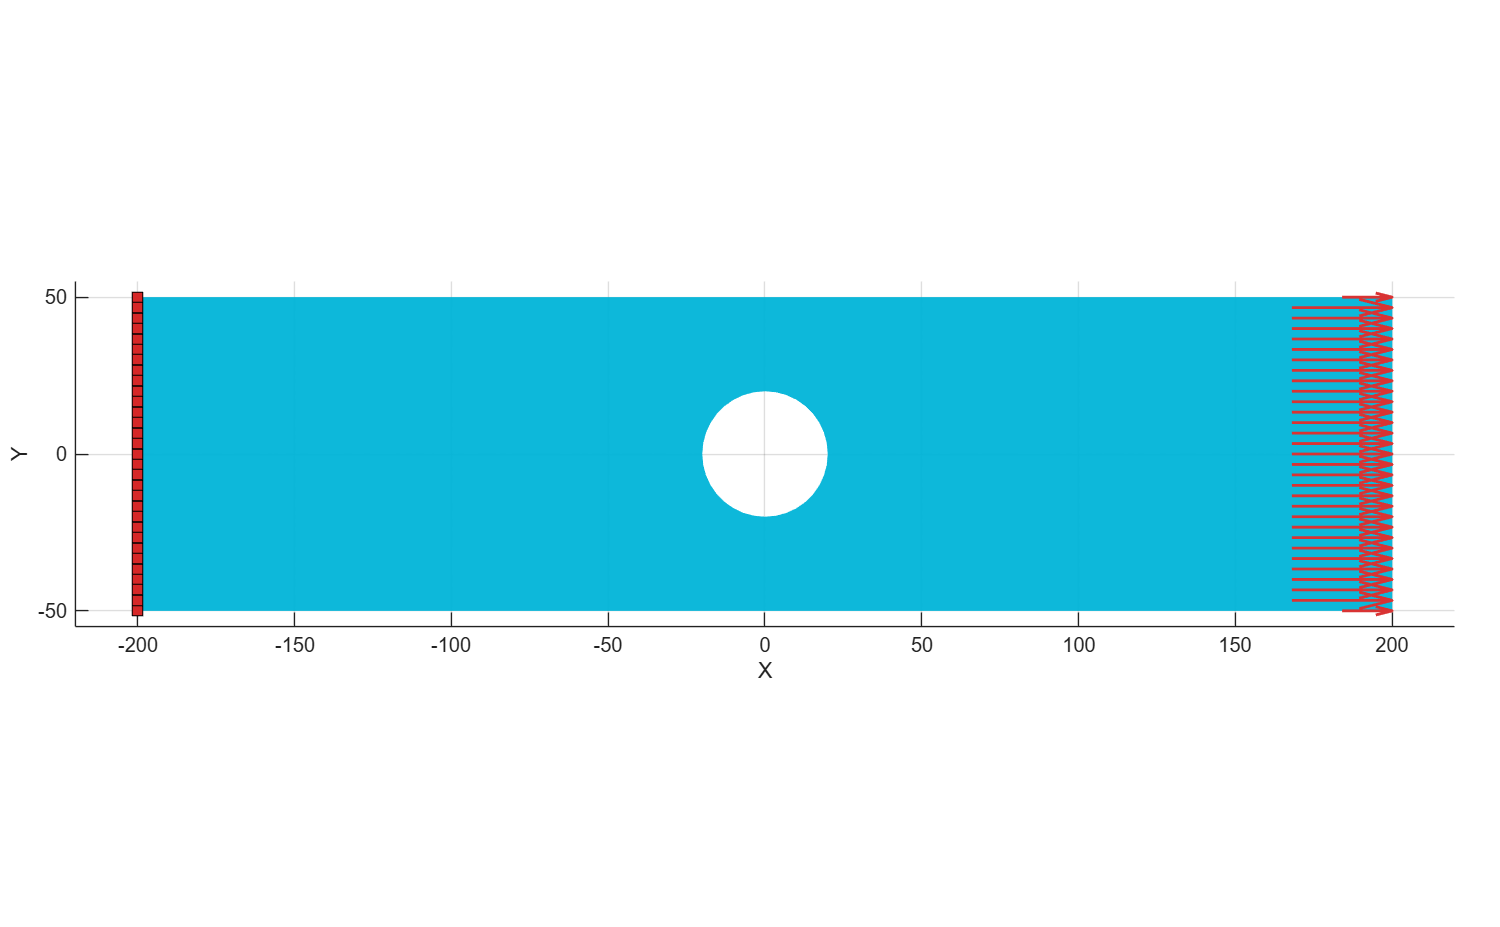

opts = opsMAT.vis.defaultPlotModelOptions;
opts.loads.showNodal=true;
opsMAT.vis.plotModel(opts=opts);

nodeResp = opsMAT.post.getNodalResponse("myODB");
ux = nodeResp.disp.ux;
maxUx = max(ux(:));
fprintf("Maximal deflection in the x-direction:\n" + ...
        "  OpenSeesMatlab: %g meters\n" + ...
        "  MATLAB PDE    : %g meters\n", ...
        maxUx, maxUxPDE);

Maximal deflection in the x-direction:
  OpenSeesMatlab: 0.222333 meters
  MATLAB PDE    : 0.222333 meters


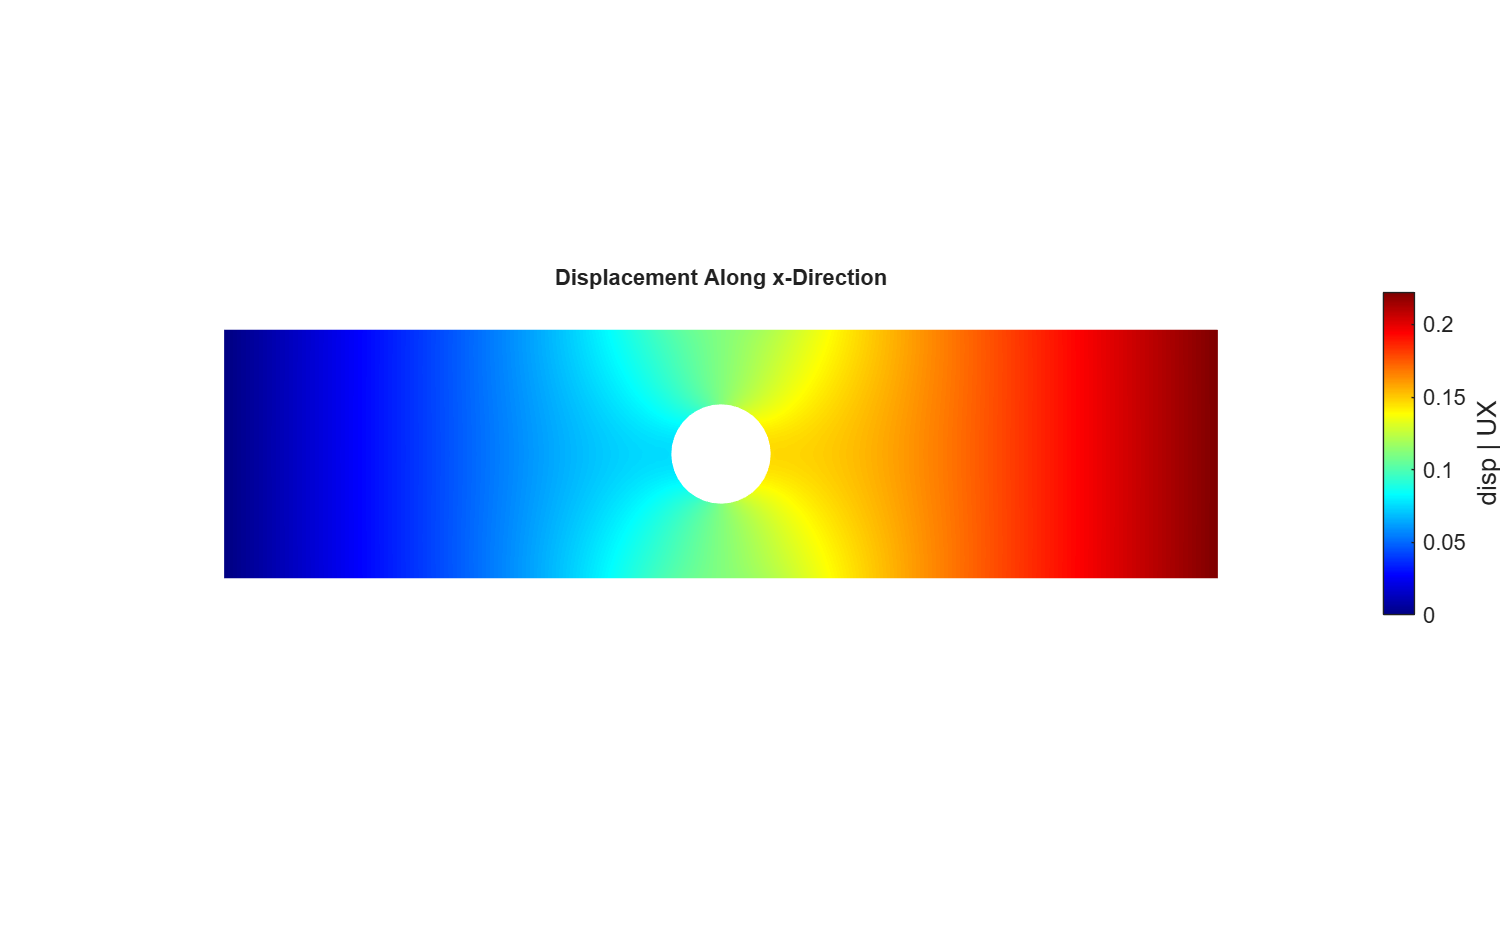


opts = opsMAT.vis.defaultPlotNodalResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;
opts.deform.show = false;

opsMAT.vis.plotNodalResponse(nodeResp, respType="disp", stepIdx="absMax", respComponent="UX", opts=opts);
colormap("jet")
axis off
title("Displacement Along x-Direction")

planeResp = opsMAT.post.getElementResponse("myODB", eleType="Plane");
sxx = planeResp.StressAtNode.sxx;
maxSxx = max(sxx(:));
fprintf("Maximal Sxx stress:\n" + ...
        "  OpenSeesMatlab: %g Pa\n" + ...
        "  MATLAB PDE    : %g Pa\n", ...
        maxSxx, maxSxxPDE);

Maximal Sxx stress:
  OpenSeesMatlab: 328.427 Pa
  MATLAB PDE    : 328.427 Pa


vm = planeResp.StressMeasureAtNode.vonMises;
maxVonMisesStress = max(vm(:));
fprintf("Maximal Von Mises stress:\n" + ...
        "  OpenSeesMatlab: %g Pa\n" + ...
        "  MATLAB PDE    : %g Pa\n", ...
        maxVonMisesStress, maxVonMisesStressPDE);

Maximal Von Mises stress:
  OpenSeesMatlab: 317.613 Pa
  MATLAB PDE    : 317.613 Pa


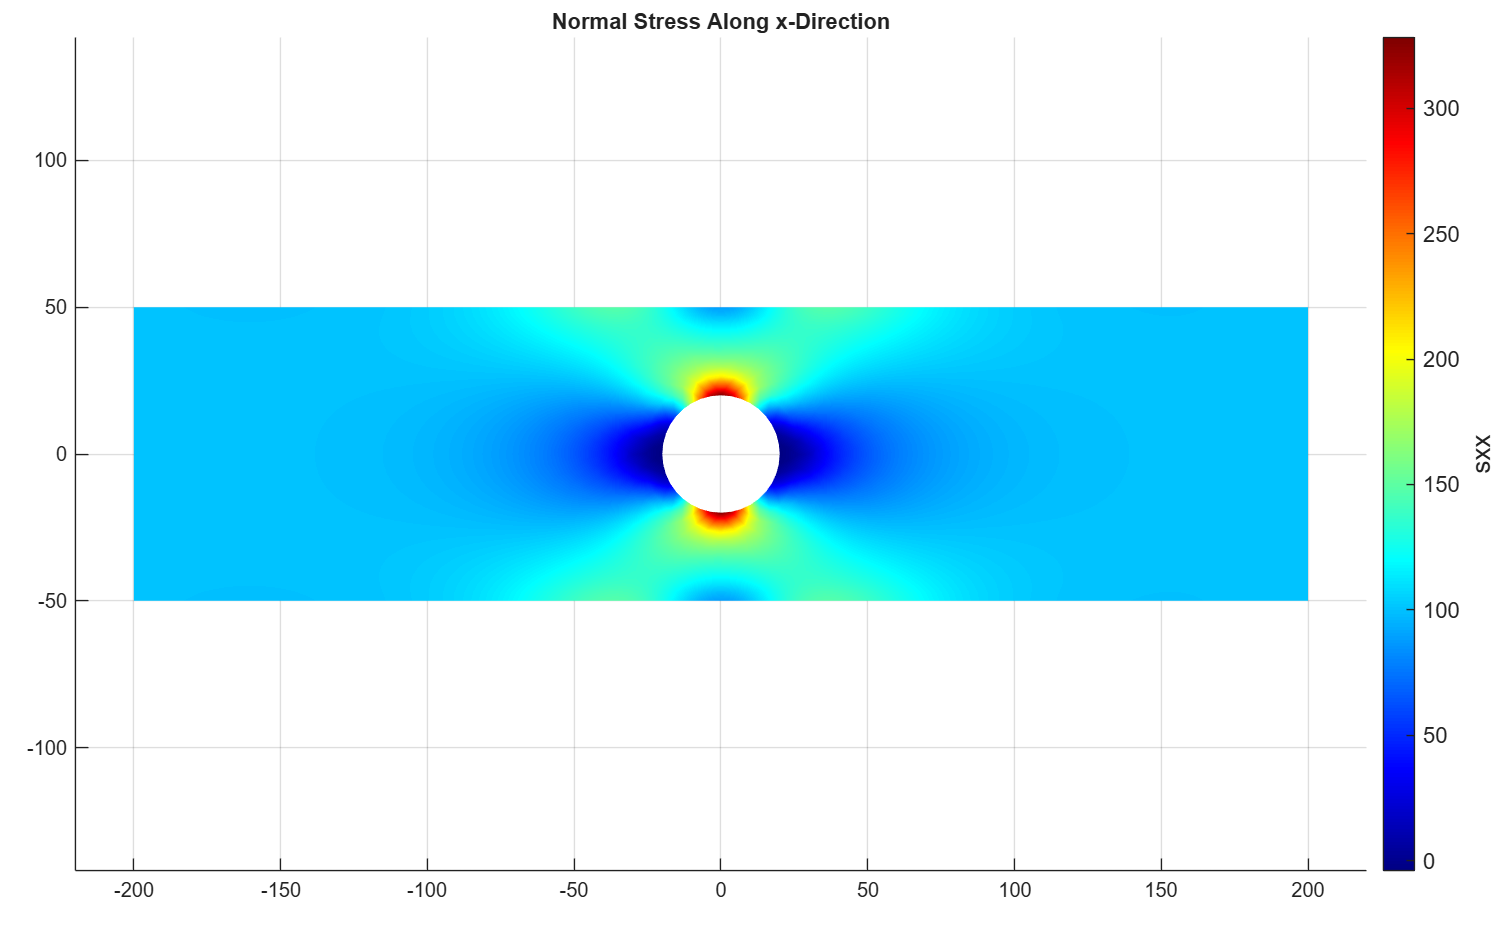



opts = opsMAT.vis.defaultPlotContinuumResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;
opts.deform.show = false;

opsMAT.vis.plotContinuumResponse(planeResp, ...
    respType="StressMeasureAtNode", respComponent="sxx", opts=opts);
axis equal
colormap("jet")
title("Normal Stress Along x-Direction")

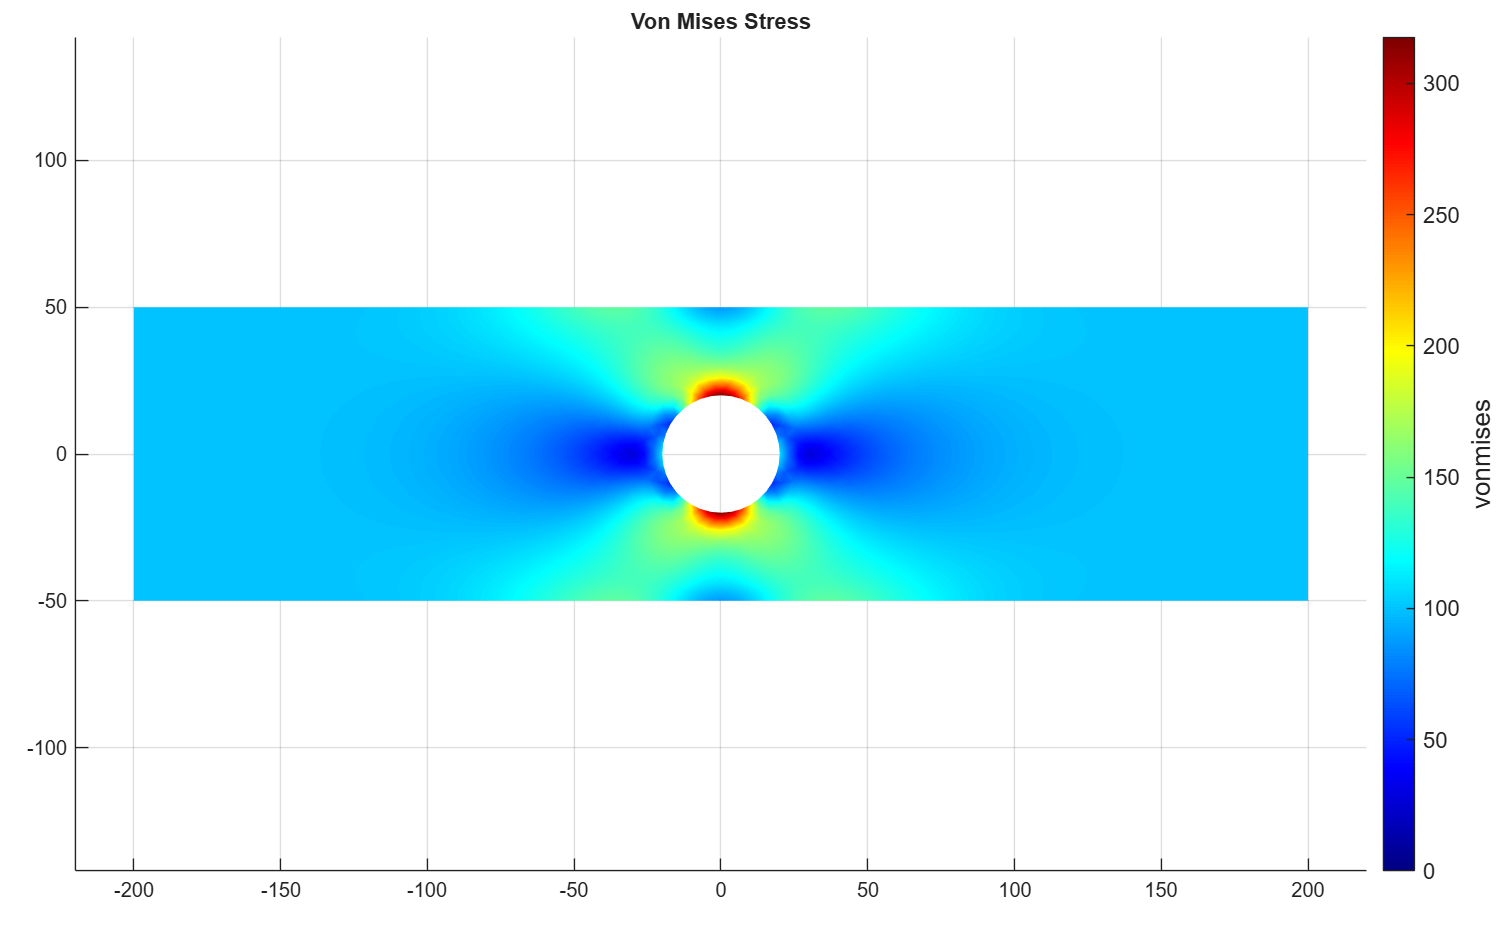

opsMAT.vis.plotContinuumResponse(planeResp, ...
    respType="StressAtNode", respComponent="vonMises", opts=opts);
axis equal
title("Von Mises Stress")
colormap("jet")

opsMAT.vis.plotContinuumResponseGUI(planeResp);

opsMAT.vis.polyscope.plotContinuumResponse(planeResp);